# **Numerical distributed-parameter transducer model**

# **for the stepped-horn with piezoelectric rings**

**2023-03-03**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

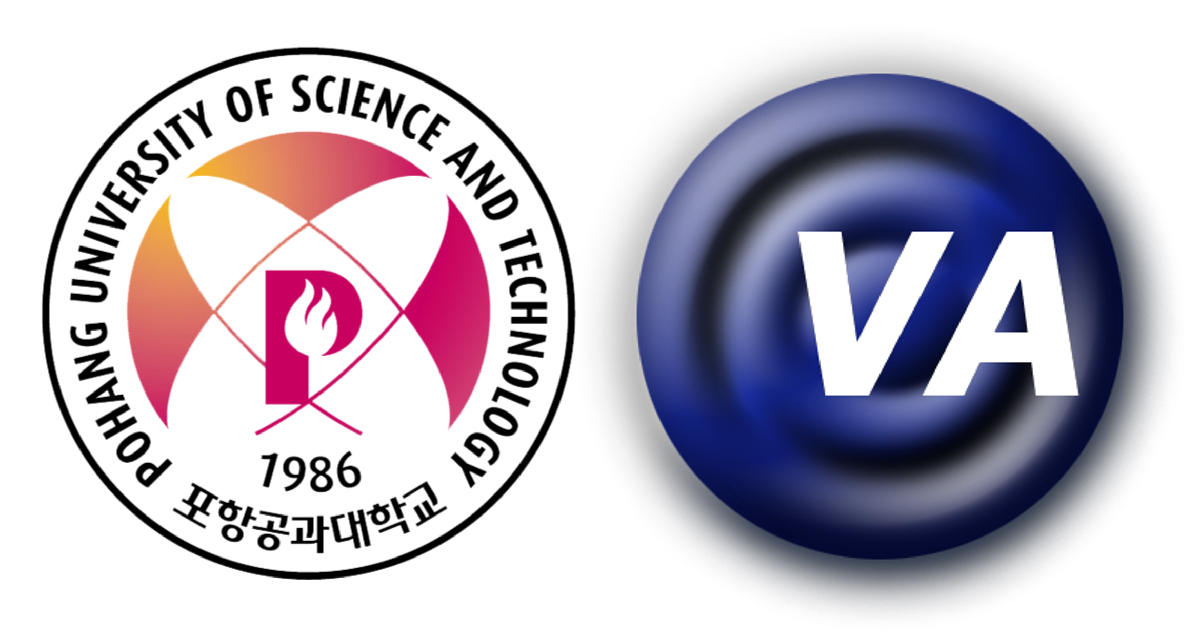

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

proj = currentProject;
time = string(datetime('now','TimeZone','local','Format','yyMMdd -HHmmss -'));

% Define the simulation frequency
f = 1e3:10:140e3;
f_no = length(f);

% Import the material properties
mat = import_material('materials_OBS.txt')

mat = 3×9 table
                              Mat           rho       Y33       nu     eps33      d33          d31        DF        v3  
                       _________________    ____    _______    ____    _____    ________    _________    _____    ______

    Aluminum           "Aluminum"           2780    7.2e+10    0.33     NaN          NaN          NaN      NaN    5089.1
    Stainless Steel    "Stainless Steel"    7800    1.9e+11    0.28     NaN          NaN          NaN      NaN    4935.5
    C-21               "C-21"               7800    6.4e+10    0.29    1400     2.88e-10    -1.31e-10    0.003    2864.5


% Import the design parameters
model_no = 4;
param = import_parameter(['parameters_1234_' num2str(model_no) '.txt'])

param = 4×6 table
    e_      l          r           A                Mat           N_piezo
    __    ______    _______    __________    _________________    _______

    1      0.012      0.007    0.00015394    "Stainless Steel"       1   
    2      0.004      0.007    0.00015394    "C-21"                  4   
    3     0.0139      0.007    0.00015394    "Aluminum"              1   
    4     0.0153    0.00075    1.7671e-06    "Aluminum"              1   


% Construct the model
e_no    = height(param);
n_start = param.e_(1);
n_end   = param.e_(end)+1;
n_no    = n_end - n_start+1;

if n_start > n_end
    disp("Error: the end index of node must be greater than start index!");
    return
end
S = sprintf("The number of elements:    %d\n" + ...
    "The number of nodes:       %d",e_no,n_no);
disp(S);

The number of elements:    4
The number of nodes:       5


% Index of piezoelectric bar
e_piezo = find(param.Mat == "C-21");

% Initialize the symbols for material properties and design parameters of elements
param = sortrows(innerjoin(param, mat))

param = 4×14 table
    e_      l          r           A                Mat           N_piezo    rho       Y33       nu     eps33      d33          d31        DF        v3  
    __    ______    _______    __________    _________________    _______    ____    _______    ____    _____    ________    _________    _____    ______

    1      0.012      0.007    0.00015394    "Stainless Steel"       1       7800    1.9e+11    0.28     NaN          NaN          NaN      NaN    4935.5
    2      0.004      0.007    0.00015394 

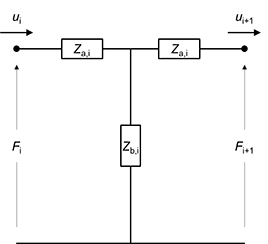

**Figure 1** The symmetric T-network circuit representation of a bar where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\left({\frac{k_{\rm{i}} l_{\rm{i}}}{2}}\right)}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{\left(k_{\rm{i}} l_{\rm{i}}\right)}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{\left(k_{\rm{i}} l_{\rm{i}}\right)}$.

By the KCL,


$$\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]

=

\left[
\matrix{
F_{i}\cr
-F_{i+1}\cr
}
\right]$$


% Calculating the bar's impedance for symmetric T-network
Z_b = zeros(f_no, e_no);  % Z_b
Z_c = zeros(f_no, e_no);  % Z_c = Z_a + Z_b
Z_d = zeros(f_no, n_no);  % Z_d for the boundary conditions of both ends

for i=1:e_no
    Z_b(:,i) = -1j*param.rho(i)*param.v3(i)*param.A(i)./(sin(2*pi*f./param.v3(i).*param.l(i)));
    Z_c(:,i) = -1j*param.rho(i)*param.v3(i)*param.A(i).*cot(2*pi*f./param.v3(i).*param.l(i));
end

The effort and flow variable vectors are $\mathbf{F}=
\left[
\matrix{
F_1\cr
F_2\cr
F_3\cr
\vdots \cr
F_{-2}\cr
F_{-1}\cr
F_0\cr
}
\right]$ and $\mathbf{u}=
\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
\vdots \cr
u_{-2}\cr
u_{-1}\cr
u_0\cr
}
\right]$ where 1 and 0 are the node's start and end indices, and the minus sign is the reversed order from the end index.

% Initialize the symbols for effort and flow variable vectors
F   = zeros(f_no, n_no);
u   = zeros(f_no, n_no);
V   = 10;

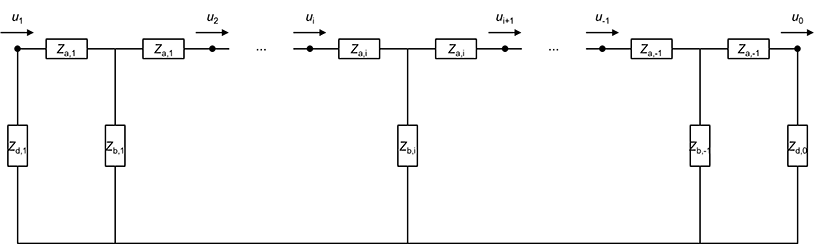

**Figure 2** The symmetric T-network circuit representation of bars mechanically connected in series and its boundary conditions of both ends

When bars are mechanically connected in series and there are the arbitrary impedances, $Z_{\rm{d}}$, at both ends without external force, $\mathbf{F}=\mathbf{Z} \cdot \mathbf{u}=[0]$.

And the impedance matrix is $Z=
\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & \cdots & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} &  \cdots & 0 & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & \cdots & 0 & 0 & 0 \cr
\vdots & \vdots & \vdots & \ddots & \vdots & \vdots & \vdots \cr
0 & 0 & 0 & \cdots & Z_{\rm{c,-3}}+Z_{\rm{c,-2}} & -Z_{\rm{b,-2}} & 0 \cr
0 & 0 & 0 & \cdots & -Z_{\rm{b,-2}} & Z_{\rm{c,-2}}+Z_{\rm{c,-1}} & -Z_{\rm{b,-1}} \cr
0 & 0 & 0 & \cdots & 0 & -Z_{\rm{b,-1}} & Z_{\rm{c,-1}}+Z_{\rm{d,0}} \cr
}
\right]$ where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\left({\frac{k_{\rm{i}} l_{\rm{i}}}{2}}\right)}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{\left(k_{\rm{i}} l_{\rm{i}}\right)}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{\left(k_{\rm{i}} l_{\rm{i}}\right)}$.

% Define the bounrady conditions of both ends
Z_d(:,1) = 0;
Z_d(:,n_no) = 0;

% Constructing the impedance matrix
Z = zeros(f_no,n_no,n_no);

Z(:,1,1)        = Z_c(:,1) + Z_d(:,1);
Z(:,1,2)        = -Z_b(:,1);
Z(:,1,3:n_no)  = 0;

for i=2:n_no-1
    Z(:,i,1:i-2)  = 0;
    Z(:,i,i-1)    = -Z_b(:,i-1);
    Z(:,i,i)      = Z_c(:,i-1) + Z_c(:,i);
    Z(:,i,i+1)    = -Z_b(:,i);
    Z(:,i,i+2:n_no)= 0;
end

Z(:,n_no, 1:n_no-2) = 0;
Z(:,n_no, n_no-1)   = -Z_b(:,n_no-1);
Z(:,n_no, n_no)     = Z_c(:,n_no-1) + Z_d(:,n_no);

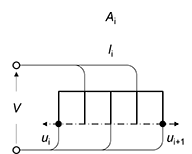

**Figure 3** 4 Piezoelectric bars mechanically connected in series and electrically in parallel

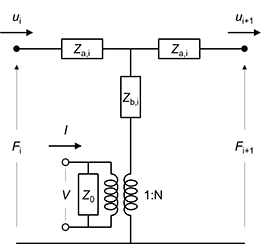

**Figure 4** The symmetric T-network circuit representation of piezoelectric bars mechanically connected in series and electrically in parallel

By KCL,

$\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]

=

\left[
\matrix{
F_{i}+NV\cr
-F_{i+1}-NV\cr
}
\right]$where $N=\frac{A_{i} \thinspace d_{33}}{l_{i} \thinspace s_{33}^{E}}\cdot N_{i}$

N = param.A(e_piezo)*param.d33(e_piezo)*param.N_piezo(e_piezo)/param.l(e_piezo)*param.Y33(e_piezo);

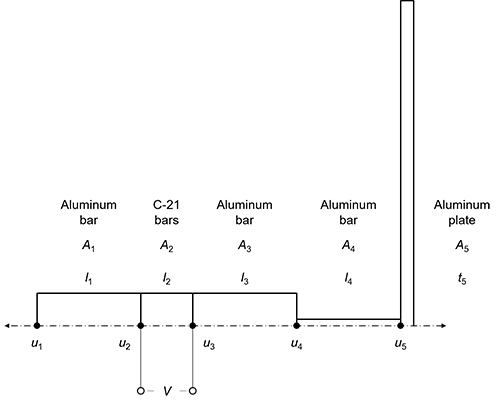

**Figure 5** Typical stepped-plate transducer

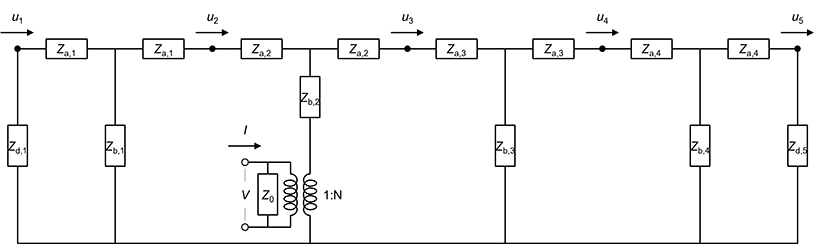

**Figure 6 **The distributed network representation of typical stepped-plate transudcer

By KCL,


$$\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & -Z_{\rm{b,3}} & 0 \cr
0 & 0 & -Z_{\rm{b,3}} & Z_{\rm{c,3}}+Z_{\rm{c,4}} & -Z_{\rm{b,4}} \cr
0 & 0 & 0 & -Z_{\rm{b,4}} & Z_{\rm{c,4}}+Z_{\rm{d,5}} \cr
}
\right]

\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
u_4\cr
u_5\cr
}
\right]

=

\left[
\matrix{
0\cr
NV\cr
-NV\cr
0\cr
0\cr
}
\right]$$


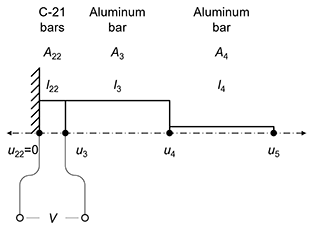

**Figure 7** The aluminum stepped amplitude transformer driven by two piezoelectric bars, C-21, fixed on one end and free on the other end

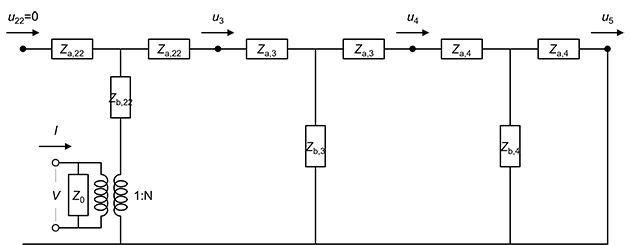

**Figure 8** The distributed network representation of the aluminum stepped amplitude transformer driven by piezoelectric bars

% For the Langevin transducer and stepped-horn

Define the boundary conditions

Define the force conditions

- Force at node 22, $F_{22}=NV$

- Force at node 3, $F_{3}=-NV$

F(:,e_piezo) = N*V;
F(:,e_piezo+1) = -N*V;

Solve $\mathbf{Z}\cdot \mathbf{u}=\mathbf{F}$

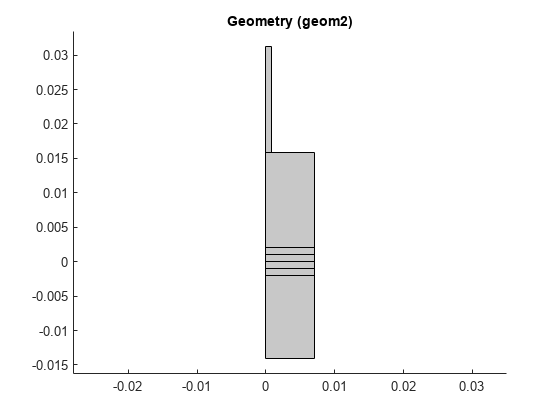

for i=1:f_no
    u(i,1:n_no) = squeeze(Z(i,1:n_no,1:n_no))\F(i,1:n_no)';
end
% createfigure_fr(f,abs(u(:,2:n_no)), string(n_start+1:n_end), 'Frequency [Hz]', 'Velocity [m/s]', 'linear', 'log')

load(['230308 -OBS_1234_' num2str(model_no) '.mat']);

if exist('model','var') == 0
    model = mphload('230119 -Stepped-horn');
end
model_.freq = mpheval(model, 'freq','dataset','dset19','outersolnum',model_no,'selection',1,'edim','point');
model_.u1 = mpheval(model,'solid2.u_tZ*1i','dataset','dset19','outersolnum',model_no,'selection',1,'edim','point');
model_.u2 = mpheval(model,'solid2.u_tZ*1i','dataset','dset19','outersolnum',model_no,'selection',2,'edim','point');
model_.u3 = mpheval(model,'solid2.u_tZ*1i','dataset','dset19','outersolnum',model_no,'selection',6,'edim','point');
model_.u4 = mpheval(model,'solid2.u_tZ*1i','dataset','dset19','outersolnum',model_no,'selection',7,'edim','point');
model_.u5 = mpheval(model,'solid2.u_tZ*1i','dataset','dset19','outersolnum',model_no,'selection',8,'edim','point');
% createfigure_fr(model_.freq.d1,abs([model_.u3.d1 model_.u4.d1 model_.u5.d1]), string(n_start+1:n_end), 'Frequency [Hz]', 'Velocity [m/s]', 'linear', 'log')

model.param.set('r4', [num2str(param.r(e_no)) ' [m]']);
mphgeom(model,'geom2')

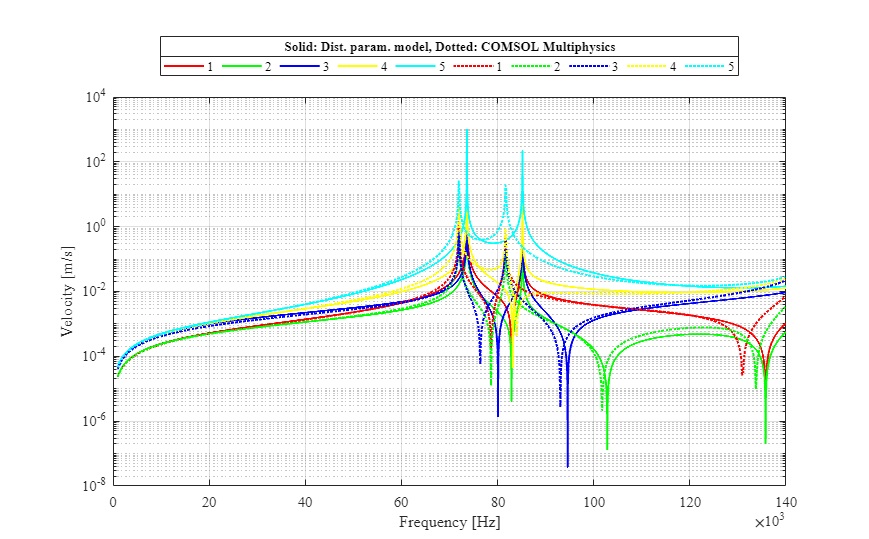


createfigure_fr_comp(f,abs(u(:,1:n_no)), ...
    model_.freq.d1,abs([model_.u1.d1 model_.u2.d1 model_.u3.d1 model_.u4.d1 model_.u5.d1]), ...
    'Solid: Dist. param. model, Dotted: COMSOL Multiphysics', ...
    string(n_start:n_end), 'Frequency [Hz]', 'Velocity [m/s]', 'linear', 'log')

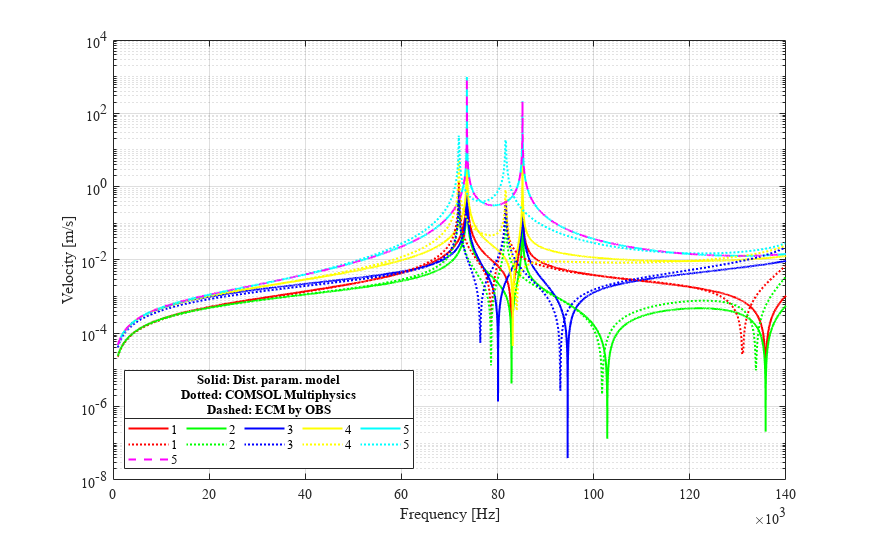


createfigure_fr_comp_OBS(f,abs(u(:,1:n_no)), ...
    model_.freq.d1,abs([model_.u1.d1 model_.u2.d1 model_.u3.d1 model_.u4.d1 model_.u5.d1]), ...
    OBS_1234(:,1), abs(OBS_1234(:,2)), ...
    ["Solid: Dist. param. model", "Dotted: COMSOL Multiphysics", "Dashed: ECM by OBS"], ...
    string(n_start:n_end), 'Frequency [Hz]', 'Velocity [m/s]', 'linear', 'log', proj, time, model_no)